# Robótica- Lab4

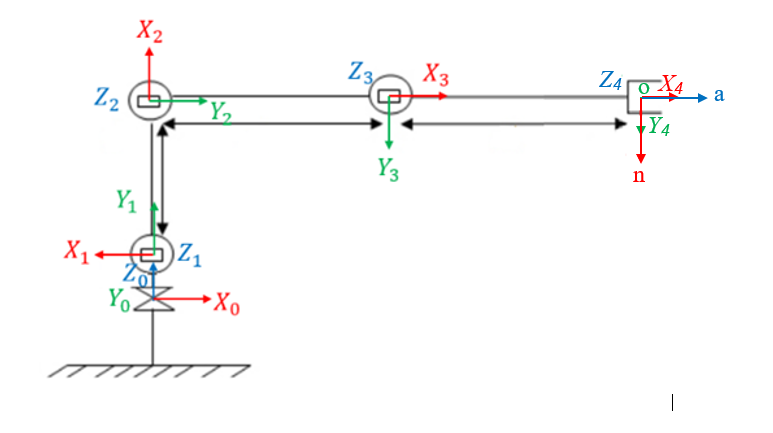

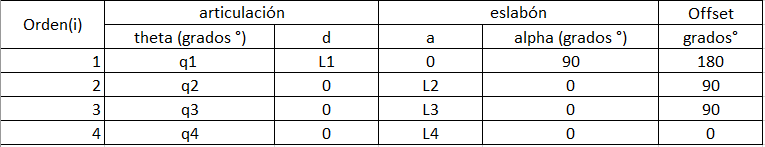

(Para que se cumpla la convención noa se hace una matriz de transformacion homogenea relacionando el frame 4 con el TCP que es el que se quiere que tenga dicha convención)

clc
clear
L1_4= 4.6; %%cm
L2_4= 10.7;
L3_4= 10.7;
L4_4= 9.5;

L(1) = Link('revolute', 'd' , L1_4 , 'a' , 0 , 'alpha' , pi/2 , 'offset' , pi , 'qlim' , [0 2*pi] ); %%pi
L(2) = Link('revolute', 'd' , 0 , 'a' , L2_4,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );     %%pi
L(3) = Link('revolute', 'd' , 0, 'a' , L3_4 ,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );      %%0
L(4) = Link('revolute', 'd' , 0 , 'a' , L4_4 , 'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );  %%pi/2

T_Tool_4=rt2tr(rotx(90,"deg")*roty(90,"deg"),[0 0 0]')

T_Tool_4 =     0.0000         0    1.0000         0
    1.0000    0.0000   -0.0000         0
   -0.0000    1.0000    0.0000         0
         0         0         0    1.0000


Robot4 = SerialLink(L,'name','Robot_4','tool',T_Tool_4)

 
Robot4 = 
 
Robot_4 (4 axis, RRRR, stdDH, fastRNE)                           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        4.6|          0|      1.571|      3.142|
|  2|         q2|          0|       10.7|          0|      1.571|
|  3|         q3|          0|       10.7|          0|          0|
|  4|         q4|          0|        9.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           


syms L1 L2 L3 L4 TH1 TH2 TH3 TH4 
T10_4 = calculaMTH(TH1+180,L1,0,90) %%(theta,d,a,alpha)

$$T10\_4 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left({\mathrm{TH}}_{1}+180\right)}{180}\right) & 0 & \sin\left(\frac{\pi \,\left({\mathrm{TH}}_{1}+180\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\left({\mathrm{TH}}_{1}+180\right)}{180}\right) & 0 & -\cos\left(\frac{\pi \,\left({\mathrm{TH}}_{1}+180\right)}{180}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T21_4 = calculaMTH(TH2+90,0,L2,0)

$$T21\_4 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right) & -\sin\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right) & 0 & L_{2}\,\cos\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right)\\ \sin\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right) & \cos\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right) & 0 & L_{2}\,\sin\left(\frac{\pi \,\left({\mathrm{TH}}_{2}+90\right)}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T32_4 = calculaMTH(TH3+90,0,L3,0)

$$T32\_4 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right) & -\sin\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right) & 0 & L_{3}\,\cos\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right)\\ \sin\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right) & \cos\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right) & 0 & L_{3}\,\sin\left(\frac{\pi \,\left({\mathrm{TH}}_{3}+90\right)}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T43_4 = calculaMTH(TH4,0,L4,0)

$$T43\_4 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right) & 0 & L_{4}\,\cos\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right)\\ \sin\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right) & 0 & L_{4}\,\sin\left(\frac{\pi \,{\mathrm{TH}}_{4}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ahora se obtiene el modelo geométrico directo en base a las MTH con las que se cuentan:

T40_4 = T10_4*T21_4*T32_4*T43_4*T_Tool_4

Teniendo el modelo geométrico directo y con los valores dados por el ejercicio es posible calcular la posición y orientación de la herramienta con respecto al marco de referencia base.

T40Subs_4_H = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 0 0 0 0]))

T40Subs_4_H =     0.0000         0    1.0000   20.2000
   -0.0000    1.0000    0.0000         0
   -1.0000   -0.0000    0.0000   15.3000
         0         0         0    1.0000


T40Subs_4_1 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -25 15 -20 20]))

T40Subs_4_1 =    -0.2346    0.4226    0.8754   20.4870
    0.1094    0.9063   -0.4082   -9.5533
   -0.9659   -0.0000   -0.2588   13.4092
         0         0         0    1.0000


T40Subs_4_2 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 35 -35 30 -30]))

T40Subs_4_2 =     0.4698   -0.5736    0.6710   10.0788
    0.3290    0.8192    0.4698    7.0573
   -0.8192   -0.0000    0.5736   19.7465
         0         0         0    1.0000


T40Subs_4_3 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -85 20 -55 17]))

T40Subs_4_3 =     0.0269    0.9962    0.0829    1.8703
   -0.3078    0.0872   -0.9474  -21.3779
   -0.9511   -0.0000    0.3090   23.7276
         0         0         0    1.0000


T40Subs_4_4 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -80 35 -55 45]))

T40Subs_4_4 =    -0.0734    0.9848    0.1574    4.3068
    0.4162    0.1736   -0.8925  -24.4251
   -0.9063   -0.0000   -0.4226   13.0097
         0         0         0    1.0000



postura_ej4Eul_H = [T40Subs_4_H(1:3,4);tr2eul(T40Subs_4_H,'deg')']

postura_ej4Eul_H =    20.2000
         0
   15.3000
    0.0000
   90.0000
   -0.0000


postura_ej4Eul_1 = [T40Subs_4_1(1:3,4);tr2eul(T40Subs_4_1,'deg')']

postura_ej4Eul_1 =    20.4870
   -9.5533
   13.4092
  -25.0000
  105.0000
   -0.0000


postura_ej4Eul_2 = [T40Subs_4_2(1:3,4);tr2eul(T40Subs_4_2,'deg')']

postura_ej4Eul_2 =    10.0788
    7.0573
   19.7465
   35.0000
   55.0000
   -0.0000


postura_ej4Eul_3 = [T40Subs_4_3(1:3,4);tr2eul(T40Subs_4_3,'deg')']

postura_ej4Eul_3 =     1.8703
  -21.3779
   23.7276
  -85.0000
   72.0000
   -0.0000


postura_ej4Eul_4 = [T40Subs_4_4(1:3,4);tr2eul(T40Subs_4_4,'deg')']

postura_ej4Eul_4 =     4.3068
  -24.4251
   13.0097
  -80.0000
  115.0000
   -0.0000


La orientación en ángulos fijos se obtiene a partir de la función "tr2rpy"

postura_ej4RPY_H = [T40Subs_4_H(1:3,4);tr2rpy(T40Subs_4_H,'deg')']

postura_ej4RPY_H =    20.2000
         0
   15.3000
         0
   90.0000
   -0.0000


postura_ej4RPY_1 = [T40Subs_4_1(1:3,4);tr2rpy(T40Subs_4_1,'deg')']

postura_ej4RPY_1 =    20.4870
   -9.5533
   13.4092
  122.3756
   61.0954
 -119.0320


postura_ej4RPY_2 = [T40Subs_4_2(1:3,4);tr2rpy(T40Subs_4_2,'deg')']

postura_ej4RPY_2 =    10.0788
    7.0573
   19.7465
  -39.3227
   42.1451
   50.6773


postura_ej4RPY_3 = [T40Subs_4_3(1:3,4);tr2rpy(T40Subs_4_3,'deg')']

postura_ej4RPY_3 =     1.8703
  -21.3779
   23.7276
   71.9357
    4.7547
  -88.4514


postura_ej4RPY_4 = [T40Subs_4_4(1:3,4);tr2rpy(T40Subs_4_4,'deg')']

postura_ej4RPY_4 =     4.3068
  -24.4251
   13.0097
  115.3376
    9.0548
  -94.2617


q4_H= [0 0 0 0] ;
q4_1= [0.2,0.4,0.7,0.1] %,0];

q4_1 =     0.2000    0.4000    0.7000    0.1000


q4_2= [-0.7, 0,0.2, -1.4] %,-0.3];

q4_2 =    -0.7000         0    0.2000   -1.4000


q4_3= [0.8, 0.9, -0.6, 0.4] %, 0];

q4_3 =     0.8000    0.9000   -0.6000    0.4000


q4_4= [0, 0, 1.5, 3/4] % 0];

q4_4 =          0         0    1.5000    0.7500



Robot4.fkine(q4_H)

ans =     1.0000    0.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000   -0.0000
    0.0000    0.0000    1.0000   35.5000
         0         0         0    1.0000


Robot4.fkine(q4_1)

ans =     0.3551   -0.1987    0.9135   22.1074
    0.0720    0.9801    0.1852    4.4814
   -0.9320    0.0000    0.3624   22.7512
         0         0         0    1.0000


Robot4.fkine(q4_2)

ans =     0.2771    0.6442   -0.7129   -5.1463
   -0.2334    0.7648    0.6004    4.3347
    0.9320    0.0000    0.3624   29.2291
         0         0         0    1.0000


Robot4.fkine(q4_3)

ans =     0.5329   -0.7174    0.4488   12.3064
    0.5487    0.6967    0.4621   12.6712
   -0.6442    0.0000    0.7648   28.7393
         0         0         0    1.0000


Robot4.fkine(q4_4)

ans =    -0.6282    0.0000    0.7781   18.0649
    0.0000    1.0000   -0.0000   -0.0000
   -0.7781    0.0000   -0.6282   10.0892
         0         0         0    1.0000


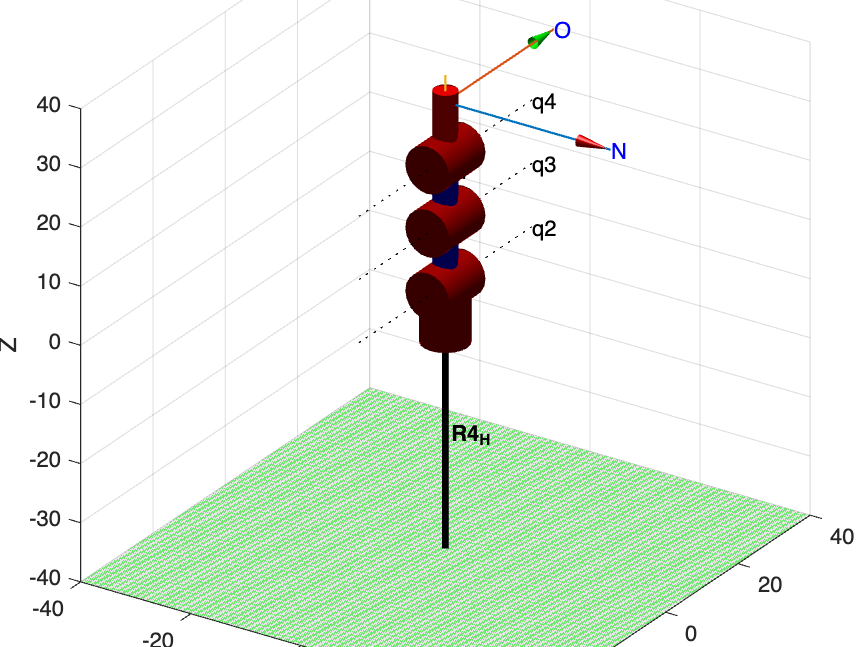

 
Robot4.name = 'R4_H';
ws = [-40 40 -40 40 -40 40];
figure()
Robot4.plot(q4_H,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

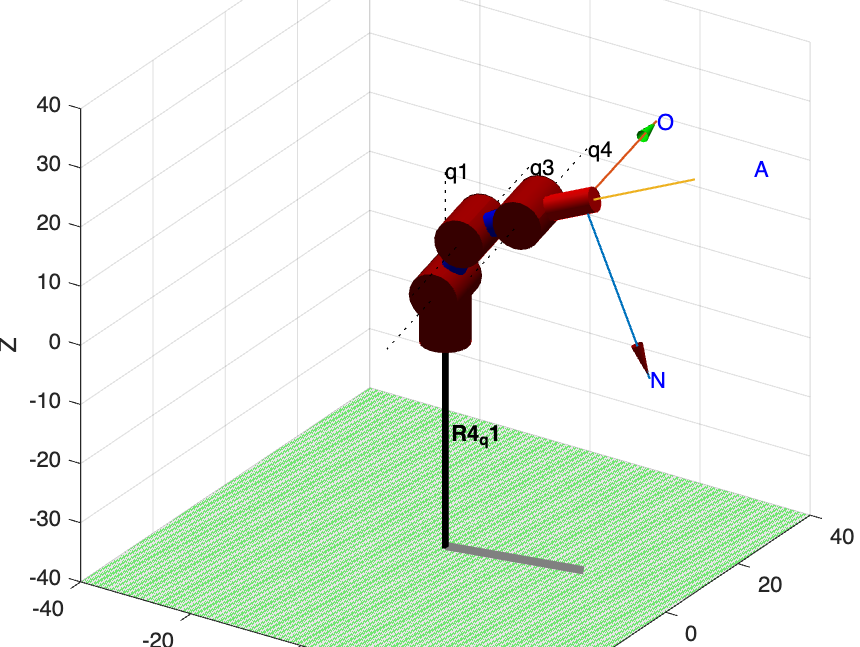


Robot4.name = 'R4_q1';
figure()
Robot4.plot(q4_1,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

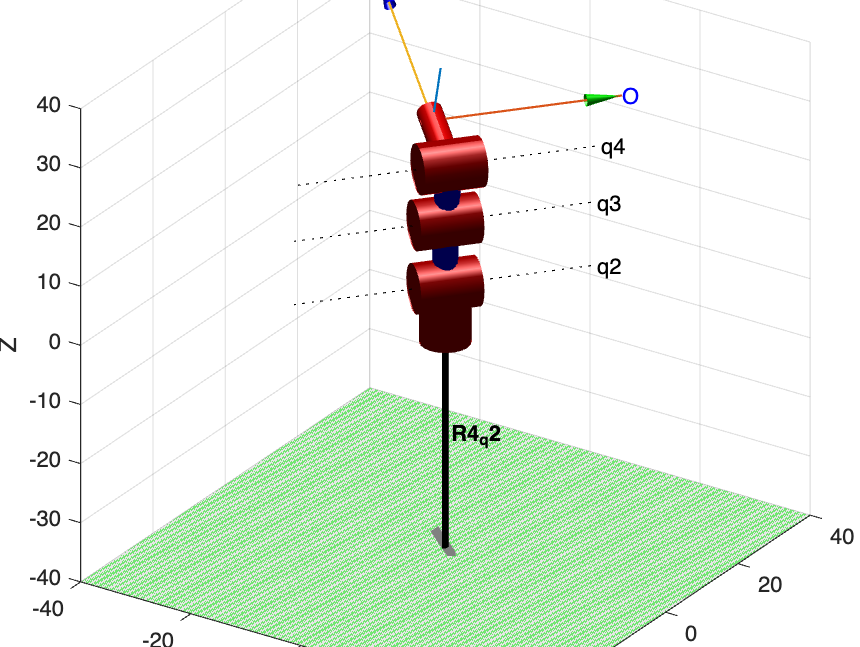


Robot4.name = 'R4_q2';
figure()
Robot4.plot(q4_2,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

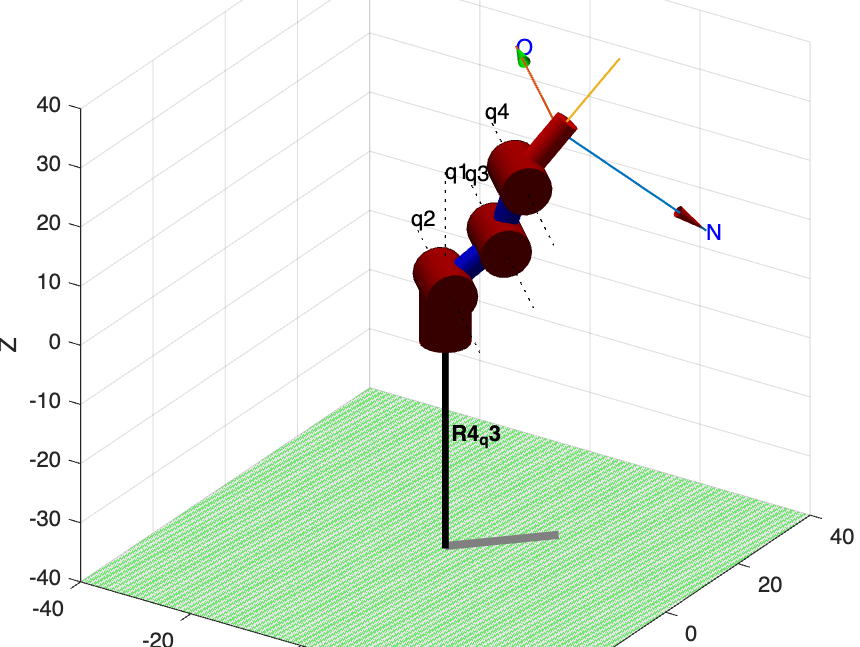


Robot4.name = 'R4_q3';
figure()
Robot4.plot(q4_3,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

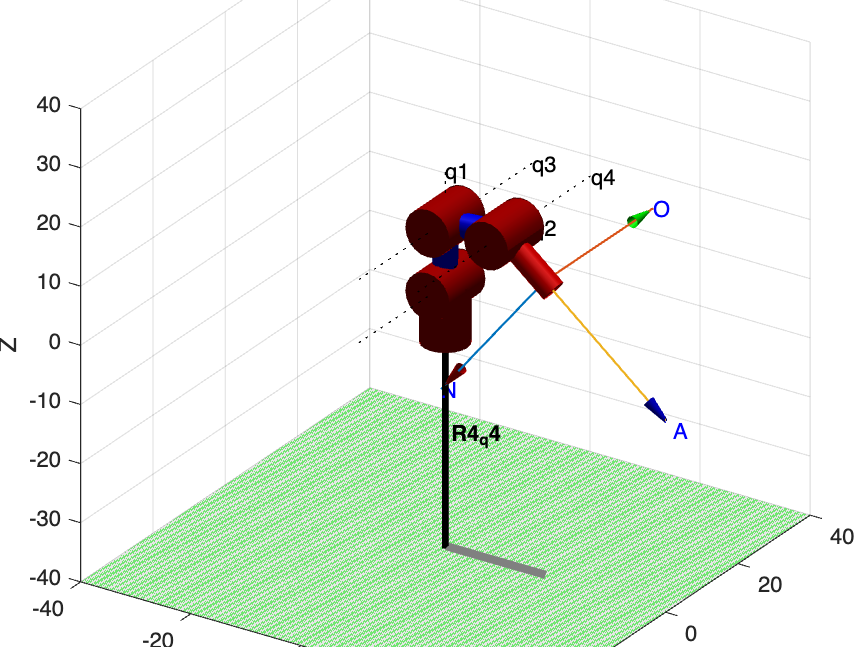


Robot4.name = 'R4_q4';
figure()
Robot4.plot(q4_4,'workspace',ws,'noa','jaxes')
view([33.28 26.14])


%Robot4.teach()

%Funcion para calcular la MTH segun:

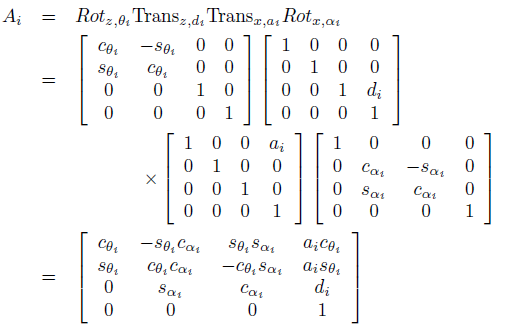

function [Res] = calculaMTH(theta_i,d_i,a_i,alpha_i)
Res = [cosd(theta_i) -sind(theta_i)*cosd(alpha_i) sind(theta_i)*sind(alpha_i) a_i*cosd(theta_i); sind(theta_i) cosd(theta_i)*cosd(alpha_i) -cosd(theta_i)*sind(alpha_i) a_i*sind(theta_i); 0 sind(alpha_i) cosd(alpha_i) d_i; 0 0 0 1];
end